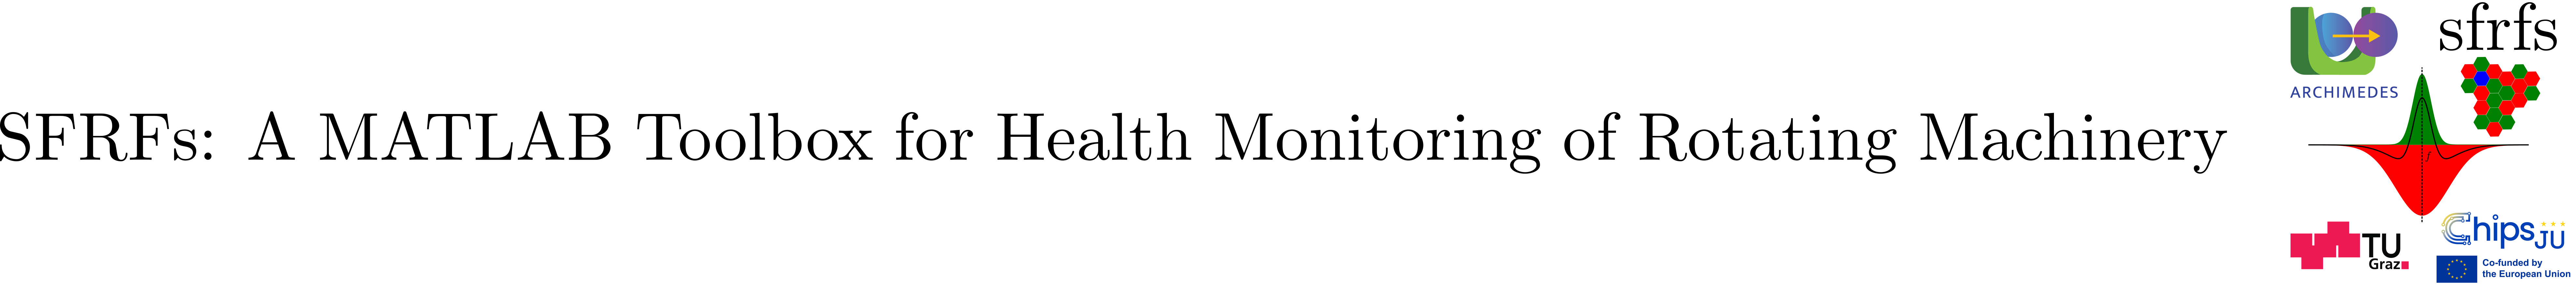

# BandMapSchema

## Summary

`BandMapSchema` provides constant string keys for `containers.Map` records that describe a single frequency-band instance used in receptive-field constructions.

## Description

This class standardizes how band-level metadata is accessed across components that manipulate dictionary-based records.

It ensures that harmonic indices, sideband structure, band definitions, and human-readable labels are represented using stable, shared identifiers, avoiding hard-coded strings and ad hoc conventions across the toolbox.

### Defined keys

### Typical usage

Used when representing a single harmonic/sideband component as a dictionary entry, for example when expanding fault-frequency families into structured band records.

This schema allows consistent interpretation of:

- which harmonic is being addressed,

- whether modulation is present,

- and how the band is labeled for traceability and visualization.

### Notes

- Applies only to `containers.Map` records, not to tables or structs.

- Complements table-based schemas defined in `+tables.`

- Intended for fine-grained, band-level metadata.

### See also

[`structs.OpponentBandsSchema`](matlab:open('./OpponentBandsSchema.mlx')), [`BearingFrequencyBands`](matlab:open('./BearingFrequencyBands.mlx')), [`FaultFrequencyBands`](matlab:open('./BearingFrequencyBands.mlx'))

## Example

% Example: construct and access a single band-map record

import dicts.BandMapSchema
import structs.OpponentBandsSchema

ft = SFRFsParametersRollingBearings.OUTER_RACE_FAULT_TYPE_NAME;
code = BearingFrequencyBands.BPFO_CODE;

% Define center/surround band limits
bands = struct();
bands.(OpponentBandsSchema.CENTER)   = [95, 105];
bands.(OpponentBandsSchema.SURROUND) = [90, 110];

% Create a band map using schema keys
m = containers.Map('KeyType','char','ValueType','any');
m(BandMapSchema.BANDS)    = bands;
m(BandMapSchema.HARMONIC) = 1;
m(BandMapSchema.SIDEBAND) = 0;
m(BandMapSchema.LABEL)    = "1" + string(code);

% Access entries via schema keys
b   = m(BandMapSchema.BANDS);
h   = m(BandMapSchema.HARMONIC);
sb  = m(BandMapSchema.SIDEBAND);
lbl = m(BandMapSchema.LABEL);

disp("Band: " + lbl + " (h=" + h + ", sb=" + sb + ")");

Band: 1Fo (h=1, sb=0)


disp("Center band: [" + b.(OpponentBandsSchema.CENTER)(1) + ", " + ...
                 b.(OpponentBandsSchema.CENTER)(2) + "] Hz");

Center band: [95, 105] Hz


disp("Surround band: [" + b.(OpponentBandsSchema.SURROUND)(1) + ", " + ...
                   b.(OpponentBandsSchema.SURROUND)(2) + "] Hz");

Surround band: [90, 110] Hz


disp(m.keys)

    {'Bands'}    {'Harmonic'}    {'Label'}    {'Sideband'}



## API documentation

### MATLAB help

help dicts.BandMapSchema

  BandMapSchema  Key constants for receptive-field band map entries

    Documentation for dicts.BandMapSchema



## Source code

The source of the class can be found in [BandMapSchema](matlab:open('../../+dicts/BandMapSchema.m')).

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).